% =============================================
% RMS DELAY SPREAD CALCULATION FROM CIR (Real Measurements)
% =============================================

%clc; clear; close all;

%% Load CIR Data (Replace with your data)
% Format: h = [sample1; sample2; ...; sample281] (complex or real)
% Example: Synthetic CIR with 3 multipath components + noise
N = 281;                    % Number of samples
dt = 1e-10;                  % Sampling interval 
t = (0:N-1)' * dt;          % Time vector

rms=[];
taus = [];

% Synthetic CIR (replace with your measured data)
% h = zeros(N,1);
% h(50) = 0.8 + 0.2j;         % First path (strongest)
% h(70) = 0.3 - 0.5j;         % Second path
% h(120) = 0.1 + 0.1j;        % Third path
% h = Final_response';%h + 0.05*(randn(N,1) + 1j*randn(N,1)); % Add noise

for i = 2:10
 
    h = MeanCIRlab(i,:)';
    
    
    %% Step 1: Compute Power Delay Profile (PDP)
    P = abs(h).^2;              % Power in linear scale
    
    %% Step 2: Noise Thresholding
    threshold_percent = 0.1;     % 10% of peak power threshold
    threshold = threshold_percent * max(P);
    valid_indices = P >= threshold;
    P_clean = P(valid_indices);
    tau_clean = t(valid_indices); % Delays of valid components
    
    %% Step 3: Calculate RMS Delay Spread
    if sum(P_clean) > 0
        mean_tau = sum(P_clean .* tau_clean) / sum(P_clean);
        mean_tau_sq = sum(P_clean .* tau_clean.^2) / sum(P_clean);
        rms_delay = sqrt(mean_tau_sq - mean_tau^2);
    else
        error('Threshold too high: No valid multipath components detected.');
    end
    
    %% Display Results
    % fprintf('===== Results =====\n');
    % fprintf('Sampling Interval (dt): %.2f ns\n', dt*1e9);
    % fprintf('Mean Excess Delay: %.2f ns\n', mean_tau*1e9);
    % fprintf('RMS Delay Spread: %.2f ns\n', rms_delay*1e9);

    taus = [taus mean_tau*1e9];
    rms = [rms rms_delay*1e9];

end

===== Results =====


Sampling Interval (dt): 0.10 ns


Mean Excess Delay: 0.85 ns


RMS Delay Spread: 0.25 ns


rms = 0.2484

===== Results =====


Sampling Interval (dt): 0.10 ns


Mean Excess Delay: 0.93 ns


RMS Delay Spread: 0.29 ns


rms =     0.2484    0.2936


===== Results =====


Sampling Interval (dt): 0.10 ns


Mean Excess Delay: 1.04 ns


RMS Delay Spread: 0.32 ns


rms =     0.2484    0.2936    0.3158


===== Results =====


Sampling Interval (dt): 0.10 ns


Mean Excess Delay: 1.29 ns


RMS Delay Spread: 0.27 ns


rms =     0.2484    0.2936    0.3158    0.2746


===== Results =====


Sampling Interval (dt): 0.10 ns


Mean Excess Delay: 1.36 ns


RMS Delay Spread: 0.29 ns


rms =     0.2484    0.2936    0.3158    0.2746    0.2902


===== Results =====


Sampling Interval (dt): 0.10 ns


Mean Excess Delay: 1.46 ns


RMS Delay Spread: 0.32 ns


rms =     0.2484    0.2936    0.3158    0.2746    0.2902    0.3206


===== Results =====


Sampling Interval (dt): 0.10 ns


Mean Excess Delay: 1.71 ns


RMS Delay Spread: 0.28 ns


rms =     0.2484    0.2936    0.3158    0.2746    0.2902    0.3206    0.2800


===== Results =====


Sampling Interval (dt): 0.10 ns


Mean Excess Delay: 1.78 ns


RMS Delay Spread: 0.32 ns


rms =     0.2484    0.2936    0.3158    0.2746    0.2902    0.3206    0.2800    0.3198


===== Results =====


Sampling Interval (dt): 0.10 ns


Mean Excess Delay: 1.91 ns


RMS Delay Spread: 0.34 ns


rms =     0.2484    0.2936    0.3158    0.2746    0.2902    0.3206    0.2800    0.3198    0.3384


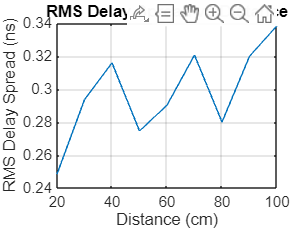

figure
plot([20:10:100],rms);
xlabel('Distance (cm)');
ylabel('RMS Delay Spread (ns)');
title('RMS Delay Spread vs Distance');
grid on;

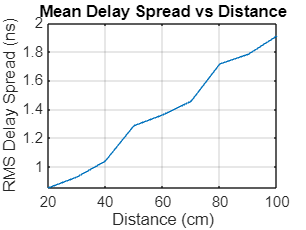

figure
plot([20:10:100], taus);xlabel('Distance (cm)');
ylabel('RMS Delay Spread (ns)');
title('Mean Delay Spread vs Distance');
grid on;